# Ćwiczenia 2. Wykresy

### Zadanie 1. Wykres funkcji sinus

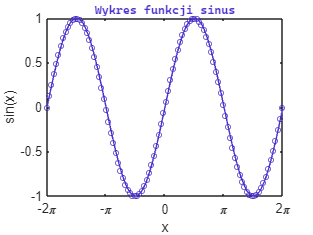

x1 = linspace(-2*pi, 2*pi);
p1 = plot(x1, sin(x1));
p1.Color = [0.3, 0.2, 0.8];
p1.Marker = "o";
p1.MarkerSize = 4;
g1 = gca;
g1.Title.String = "Wykres funkcji sinus";
g1.Title.FontName = "Cascadia Code";
g1.Title.FontSize = 9;
g1.Title.Color = [0.3, 0.2, 0.8];
g1.XLabel.String = "x";
g1.YLabel.String = "sin(x)";
g1.XTick = -2*pi:pi:2*pi;
g1.XTickLabel = {'-2\pi', '-\pi', '0', '\pi', '2\pi'};

### Zadanie 2. Trzy wykresy na jednym rysunku

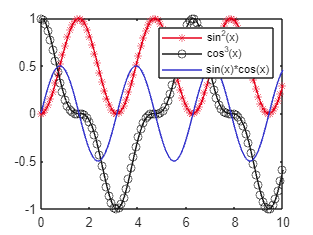

x2 = linspace(0,10);
p2 = plot(x2, sin(x2).*sin(x2), x2, cos(x2).^3, x2, sin(x2).*cos(x2));
p2(1).Color = [0.9, 0, 0.1];
p2(1).Marker = "*";
p2(2).Color = [0.1, 0.1, 0.1];
p2(2).Marker = "o";
p2(3).Color = [0.2, 0.2, 0.8];
legend('sin^2(x)','cos^3(x)','sin(x)*cos(x)')

### Zadanie 3. Brakujące dane

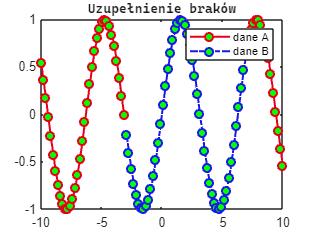

x3 = linspace(-10,10);
x3a = x3;
x3b = x3;
x3a((x3>-3)&(x3<7)) = NaN;
x3b((x3<-3)|(x3>7)) = NaN;
p3 = plot(x3a, sin(x3a), x3b, sin(x3b));
p3(1).Color = [0.9, 0, 0.1];
p3(1).LineWidth = 1.5;
p3(1).Marker = "o";
p3(1).MarkerFaceColor = [0, 1, 0];
p3(1).MarkerEdgeColor = [0.9, 0, 0.1];
p3(2).Color = [0.1, 0.1, 0.9];
p3(2).LineWidth = 1.5;
p3(2).Marker = "o";
p3(2).MarkerFaceColor = [0, 1, 0];
p3(2).MarkerEdgeColor = [0.1, 0.1, 0.9];
p3(2).LineStyle = "-.";
g3 = gca;
g3.Title.String = "Uzupełnienie braków";
g3.Title.FontName = "Cascadia Code";
g3.Title.FontSize = 10;
g3.Title.Color = [0.1, 0.1, 0.1];
legend('dane A', 'dane B');

### Zadanie 4. Funkcje parametryczne

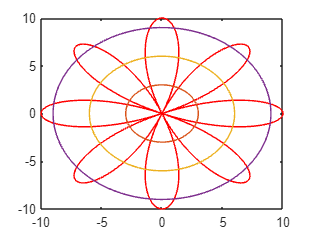

R = 8;
r = 3;
d = 5;
tu = 2*pi*lcm(r, R)/r;
%funkcja anonimowa:
x4 = @(t4)((R-r)*cos(t4)+ d*cos((R-r)/r*t4));
y4 = @(t4)((R-r)*sin(t4)- d*sin((R-r)/r*t4));
p4 = fplot(x4, y4, [0 tu]);
p4.Color = [1,0,0];
for i=r:r:3*r % i = [r 2*r 3*r]
    hold on %zeby dorysowywac do istniejacego rysunku zamiast tworzyc nowy
    fi = fplot(@(ti4)(i*cos(ti4)), ...
        @(ti4)(i*sin(ti4)), [0 2*pi]);
end
hold off

### Zadanie 5. Histogram dla podwójnego rozkładu normalnego

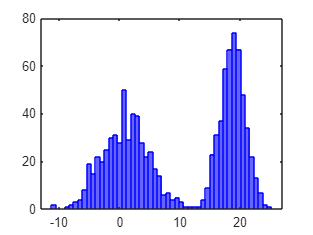

x5 = [normrnd(1, 4, 500, 1) normrnd(19, 2, 500, 1)];
%pakiet statystyczny
h5 = histogram(x5, 50);
h5.FaceColor = [0,0,1];
h5.EdgeColor = [0,0,1];

### Zadanie 7. Funkcje niejawne

% f(x,y) = 0
% r = 2;
% fn = @(a,t)(r^3 - 3*r + 4 - a.*(1 + sin(t)).^ab
% fimplicit(fn, [4 4.1 0 2*pi])

#### Funkcja 1 (przykład)

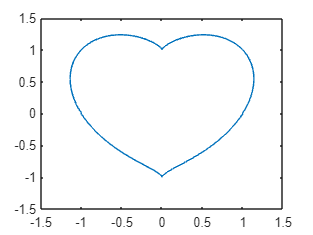

f7 = @(x,y)((x.^2 + y.^2 - 1).^3 - x.^2 .* y.^3);
f7 = fimplicit(f7, [-1.5 1.5]);

#### Funkcja 2 (zadanie)

f8 = @(x,y)((x.^2 + y.^2 - 1).*sqrt(x.^2 + y.^2)+0.75+sin(8.*sqrt(x.^2 + y.^2)).*cos(6.*(atan(y./abs(x))))-0.75.*sin(5.*atan(y./abs(x))))

f8 = function_handle with value:
    @(x,y)((x.^2+y.^2-1).*sqrt(x.^2+y.^2)+0.75+sin(8.*sqrt(x.^2+y.^2)).*cos(6.*(atan(y./abs(x))))-0.75.*sin(5.*atan(y./abs(x))))


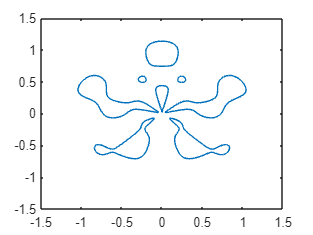

f8 = fimplicit(f8, [-1.5 1.5]);